# Grad-CAM热力图可解释性分析

使用MATLAB深度学习工具箱中的`dlgradient自动微分函数，实现`Grad-CAM算法，对深度学习图像分类模型进行可解释性分析和显著性分析。

展示神经网络预测出的指定类别，在原始输入图像上的“重点关注区域”。

2022-9-12

## 载入预训练图像分类模型

net = googlenet;

## 神经网络输入图像尺寸

inputSize = net.Layers(1).InputSize(1:2);
inputSize

inputSize =    224   224


## 载入测试图像文件

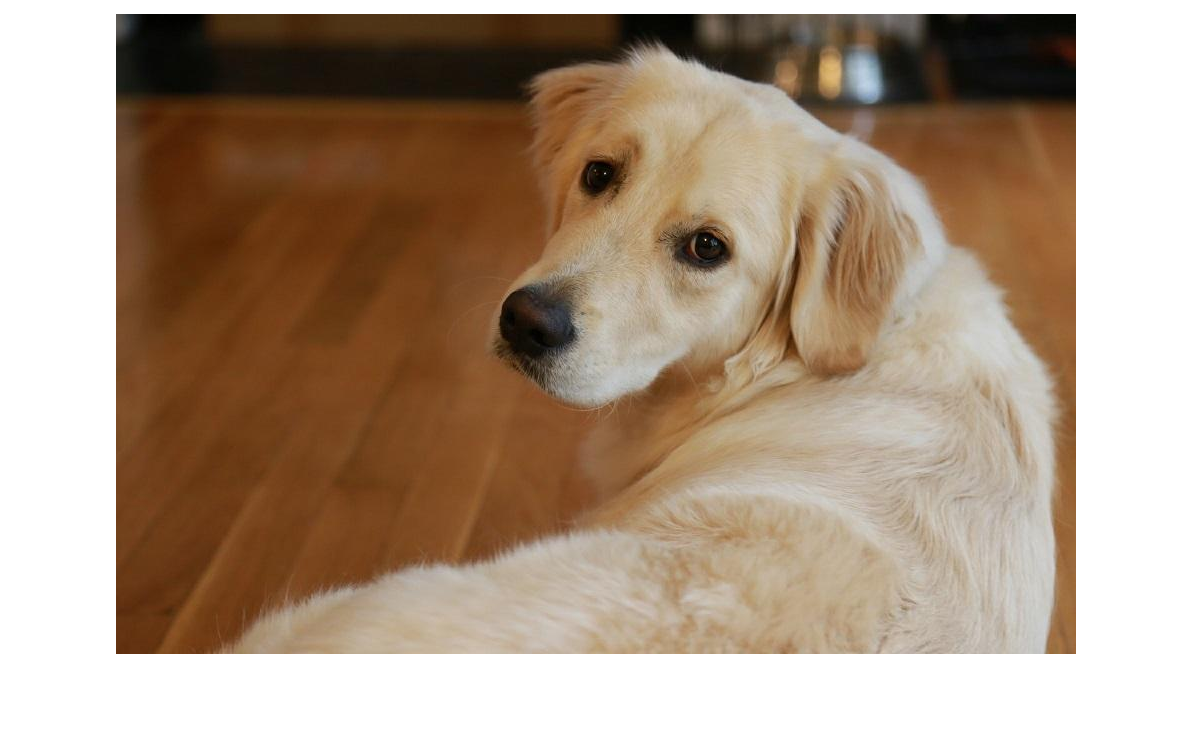

img = imread('sherlock.jpg');
imshow(img)

## 测试图像尺寸

imgSize = size(img);
imgSize

imgSize =    640   960     3


## 缩放图像至神经网络指定输入尺寸

imgResized = imresize(img, inputSize);
size(imgResized)

ans =    224   224     3


## 输入神经网络，执行图像分类预测

[classfn, score] = classify(net, imgResized);

size(score)

ans =            1        1000


classfn

classfn = categorical
     golden retriever 


## 辅助函数gradcam

辅助函数 `gradcam `用于计算 `dlnetwork `模型的Grad-CAM热力图

输入的图像 `dlImg 必须是 dlarray，便于后续自动微分求偏导。`

lgraph = layerGraph(net);
lgraph = removeLayers(lgraph, lgraph.Layers(end).Name); % 去掉最后一层分类输出层
dlnet = dlnetwork(lgraph); % 创建 dlnetwork 模型

dlImg = dlarray(single(img),'SSC'); % 将图像转为 dlarray

## 指定输出层和卷积层

analyzeNetwork(net); % 查看网络结构

softmaxName = 'prob';
featureLayerName = 'inception_5b-output';

## 计算Grad-CAM热力图

#### 第一步：计算指定卷积层输出的特征图，及对应的偏导数张量

[featureMap, dScoresdMap] = dlfeval(@gradcam, dlnet, dlImg, softmaxName, featureLayerName, classfn);

指定卷积层输出的特征图张量

size(featureMap)

ans =           20          30        1024


指定类别classfn预测概率，相对于特征图每个值的偏导数张量

size(dScoresdMap)

ans =           20          30        1024


#### 第二步：对偏导数张量，做GAP全局平均池化，求得特征图每个channel的权重

weights = sum(dScoresdMap, [1 2]);

size(weights)

ans =            1           1        1024


#### 第三步：将每个特征图通道与对应权重加权求和，得到特征图尺寸的热力图

gradcamMap = sum(featureMap .* weights, 3);
gradcamMap = extractdata(gradcamMap);

size(gradcamMap)

ans =     20    30


#### 第四步：将Grad-CAM热力图中的值控制在0-1之间

gradcamMap = rescale(gradcamMap);

#### 第五步：将Grad-CAM热力图，从特征图尺寸，缩放至原始图像尺寸

gradcamMap = imresize(gradcamMap, imgSize(1:2), 'Method', 'bicubic');

size(gradcamMap)

ans =    640   960


## 可视化Grad-CAM热力图

AlphaData 透明度，越小，越接近原图，越大，越接近热力图

jet 配色方案，值越小，越深蓝，值越大，越深红

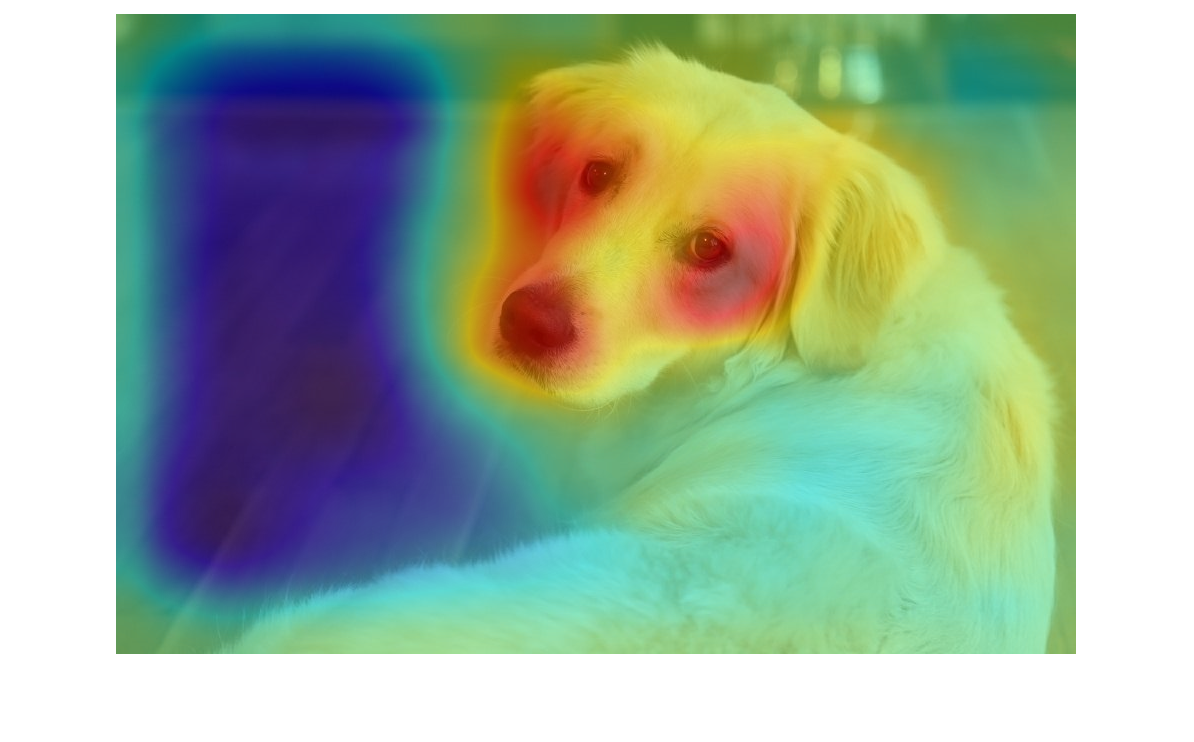

imshow(img);
hold on;
imagesc(gradcamMap,'AlphaData',0.5);
colormap jet
hold off;

## 辅助函数

function [featureMap, dScoresdMap] = gradcam(dlnet, dlImg, softmaxName, featureLayerName, classfn) % 输出指定卷积层的特征图张量，及对应的偏导数张量
[scores, featureMap] = predict(dlnet, dlImg, 'Outputs', {softmaxName, featureLayerName}); % 前向预测，获得softmax层和指定卷积层的特征图张量
classScore = scores(classfn);                                                             % 获得指定类别的预测概率
dScoresdMap = dlgradient(classScore,featureMap);                                          % 计算指定类别预测概率，相对于特征图每个值的偏导数，得到对应的偏导数张量
end